A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = [1 0 0 0];
D = [0];

sys = ss(A,B,C,D);

G = tf(sys)

A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];

eig_A = eig(A)

tau_sp = -1/real(eig_A(1))
tau_ph = -1/real(eig_A(3))

A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = [1 0 0 0];

Co = ctrb(A,B);
rank_Co = rank(Co)

Ob = obsv(A,C);
rank_Ob = rank(Ob)


A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = [1 0 0 0];
D = [0];

sys = ss(A,B,C,D);


[n,~]=size(A);
[~,m]=size(B);
p=size(C,1);

T=zeros(n+m+1,n+m+1);
T(1:n,1:n)=A;
T(1:n,n+1:n+m)=B;
T(n+m+1:n+m+1,1:n)=C;

T=T';

digraph_data = digraph(T)
figure
h=plot(digraph_data)
for i=n+1:n+m
    highlight(h,i,'NodeColor','green');
end

for i=n+m+1:n+m+1
    highlight(h, i, 'NodeColor', 'r');
end


A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = eye(4);
D = [0];

sys = ss(A,B,C,D);

t = 0:0.5:50;

figure
step(sys,t)
grid on

% Sprungoptionen konfigurieren (z.B. Höhe = -5)
opt = stepDataOptions('StepAmplitude', 0.05);

% Sprungantwort berechnen
[y, t] = step(sys, t, opt);

% Plotten
plot(t, y, 'LineWidth', 2);
grid on;
xlabel('Zeit in s');
ylabel('Ausgang y(t)');
title('Sprungantwort');


A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = eye(4);
D = [0];

sys = ss(A,B,C,D);

figure
impulse(sys)
grid on
title('Impulsantwort')


A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = [1 0 0 0];
D = [0];

sys = ss(A,B,C,D);

t = 0:0.5:50;
u = sin(0.5 * t);

% Systemantwort berechnen
[y, t] = lsim(sys, u, t);

% Plotten
figure;
plot(t, u, 'b--', t, y, 'r', 'LineWidth', 1.5);
xlabel('Zeit t [s]');
ylabel('Amplitude');
legend('Eingang (sin)', 'Systemantwort');
title('Systemantwort auf harmonische Anregung');
grid on;


A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = [1,0,0,0];
D = [0];

sys = ss(A,B,C,D);

figure
bode(sys)
grid on

A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = [1,0,0,0];
D = [0];

sys = ss(A,B,C,D);

sys_rnf = canon(sys,'companion');

A_rnf = sys_rnf.A
B_rnf = sys_rnf.B
C_rnf = sys_rnf.C
D_rnf = sys_rnf.D;


A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = [1,0,0,0];
D = [0];

sys = ss(A,B,C,D);
sys_onf = canon(sys,'modal');

A_onf = sys_onf.A
B_onf = sys_onf.B
C_onf = sys_onf.C
D_onf = sys_onf.D

A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = [1,0,0,0];
D = [0];

[V,D_eig] = eig(A);

A_diag = inv(V)*A*V
B_diag = inv(V)*B


A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = eye(4);
D = zeros(4,1);

U0=20;

sys = ss(A,B,C,D);

G_u = tf(sys(1));
Cpid_u = pidtune(G_u,'PID');
Cpid_u_P = Cpid_u.Kp

Cpid_u_P = 0.0150

Cpid_u_I = Cpid_u.Ki

Cpid_u_I = 0.0041

Cpid_u_D = Cpid_u.Kd

Cpid_u_D = 0.0137


G_alpha = tf(sys(2));
Cpid_a = pidtune(G_alpha,'PID');
Cpid_a_P = Cpid_a.Kp

Cpid_a_P = -5.7837

Cpid_a_I = Cpid_a.Ki

Cpid_a_I = -41.6233

Cpid_a_D = Cpid_a.Kd

Cpid_a_D = -0.0734


G_q = tf(sys(3));
Cpid_q = pidtune(G_q,'PID');
Cpid_q_P = Cpid_q.Kp

Cpid_q_P = -0.3304

Cpid_q_I = Cpid_q.Ki

Cpid_q_I = -6.9313

Cpid_q_D = Cpid_q.Kd

Cpid_q_D = -0.0039


G_theta = tf(sys(4));
Cpid_t = pidtune(G_theta,'PID');
Cpid_t_P = Cpid_t.Kp

Cpid_t_P = -0.0557

Cpid_t_I = Cpid_t.Ki

Cpid_t_I = -0.0217

Cpid_t_D = Cpid_t.Kd

Cpid_t_D = -0.0357

A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = [1,0,0,0];
D = [0];

p_des = [-5 -6 -7 -9];
%nur Wunschpole
K = place(A,B,p_des)

K =    18.1306    0.6290   -0.4551   -3.0211



sys =
 
  A = 
            x1       x2       x3       x4
   x1  -0.1055  -0.2651        0  -0.3535
   x2  -0.3535   -12.05        1        0
   x3    1.361   -29.82   -3.849        0
   x4        0        0        1        0
 
  B = 
            u1
   x1        0
   x2  -0.7679
   x3   -25.22
   x4        0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


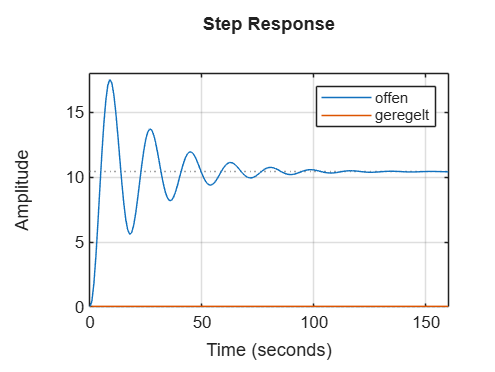

Acl = A-B*K;


A = [-0.1055   -0.2651   0  -0.3535;
    -0.3535 -12.0521   1    0;
    1.3609  -29.8208   -3.8495    0;
    0      0       1       0];
B = [0;
    -0.7679;
    -25.2170;
    0];
C = [1,0,0,0];
D = [0];

Q = diag([1 1 10 50]);
R = 1;

K_lqr = lqr(A,B,Q,R)

K_lqr =     0.1773    0.9786   -3.0876   -7.1021


Acl_lqr = A-B*K_lqr;

